parameters;
BusDeclaration;


grav = 9.81;

lb = abs(Body.length_motor(1))/1000;
lf = Femur.length; lt = Tibia.length; lf_o = Femur.offset; lt_o = Tibia.offset;
lp = Piston.length/1000;

## Variables to change what is run

% run simulink
simulink = true;

% animation of monoped
animate = true;

% front or back leg in animation (set front to true or false)
front = false;
side = -1; % -1 = back, 1 = front

% default parameters
Init.CPG = [0.02,1.02];
Init.q = [0, 0.5, th_calc(pi/2-0.5,0), 0];
Init.dq = [1,0,0,0];
Init.F = [0,0];

tst = 0.08; kx = 0.08; tsw = 0.33;
osc_param = [tst,tsw,kx];

% use PSO polynomial fit
out = [];
polyfitVal = false;
if (polyfitVal)

    dx_fit = [6.8654, -0.2095];

    load('PSO_runs/fits/fit_back.mat');

    tst = 0.1;
    kx = 0.2;

% dx = 0.5; tst = 0.09; kx = 0.08;

    x = tst;
    y = kx;

    % Init.dq(1) = polyval(dx_fit,y);

    tsw = feval(fit_back,x,y);

    osc_param = [tst;tsw;kx];
end

% use PSO individual run
runSol = false;
if runSol
    out = load("PSO_runs/run64.mat");
    % try
    %     out = out.out;
    % catch
    %     out = out;
    % end
    % out = load("results/run1.mat");
    BestSol = out.out.BestSol; simParams = out.simParams;
    Init.CPG = [BestSol.Position(1),BestSol.Position(2)];
    Init.q(2) = BestSol.Position(3);
    Init.dq(1) = BestSol.Position(5);

    Init.q(3) = th_calc(pi/2 - side*simParams.kx*BestSol.Position(1),0);

    [dx_osc,~] = CPG_Oscillator(Init.CPG(1),Init.CPG(2),1,0,simParams.tst,BestSol.Position(4));
    Init.dq(3) = dth_calc(pi/2 - side*simParams.kx*BestSol.Position(1),0,-side*dx_osc*simParams.kx,0);
    
    osc_param = [simParams.tst; BestSol.Position(4);  simParams.kx];
    out.init.y = Init.q(2);
    out.init.th = Init.q(3);
    out.init.dx = Init.dq(1);
    out.init.dth = Init.dq(3);
    out.cpg = [0;1];

    tst = simParams.tst; tsw = BestSol.Position(4); kx = simParams.kx;
    % save("PSO_runs/run1.mat","out");
    % osc_param = [simParams.tst; 0.61;  simParams.kx];
end

% use individual trajectory optimisation run
runTraj = false;
if runTraj
    out = load("TrajOpt_runs\run_0p50ms.mat");
    out = out.out;

    Init.CPG = [out.cpg(1,1),out.cpg(2,1)];
    Init.q = out.q(1:4,1)';
    Init.dq = out.q(5:8,1)';
    Init.F = out.q(9:10,1)';

    tst = out.tst(1); tsw = out.tsw(1); kx = out.kx(1);
    osc_param = [out.tst(1); out.tsw(1);  out.kx(1)];

    out.thk = zeros(1,out.N); out.tha = zeros(1,out.N);
    out.dthk = zeros(1,out.N); out.dtha = zeros(1,out.N);
    out.foot = zeros(4,out.N);

    for k = 1:out.N
        out.thk(k) = thk_calc(out.q(3,k),out.q(4,k));
        out.tha(k) = tha_calc(out.q(3,k),out.q(4,k));
        out.dthk(k) = dthk_calc(out.q(3,k),out.q(4,k),out.q(7,k),out.q(8,k));
        out.dtha(k) = dtha_calc(out.q(3,k),out.q(4,k),out.q(7,k),out.q(8,k));

        out.foot(:,k) = foot_Func(out.q(1,k),out.q(2,k),out.q(3,k),out.q(4,k),out.thk(k),out.tha(k),out.q(5,k),out.q(6,k),out.q(7,k),out.q(8,k),out.dthk(k),out.dtha(k));
    end
end

% use trajectory optimisation polynomial fits
% note this is currently not working
polyTraj = false;
if polyTraj
    dx = 0.3;

    load('OscParamsolver/fits/fit2.mat');

    tst = polyval(tst_sol,dx);
    kx = polyval(kx_sol,dx);
    tsw = polyval(tsw_sol,dx);

    Init.CPG = [0,1];
    [dx_osc,~] = CPG_Oscillator(Init.CPG(1),Init.CPG(2),1,0,tst,tsw);

    Init.q = [0,0.52,th_calc(pi/2,0),0];
    Init.dq = [dx,0,dth_calc(pi/2,0,kx*dx_osc,0),0];
    Init.F = [0,-453];
    % 
    osc_param = [tst; tsw;  kx];
    
end

% save all parameters to file for simulation
out.init.y = Init.q(2);
out.init.th = Init.q(3);
out.init.dx = Init.dq(1);
out.init.dth = Init.dq(3);
out.init.F = Init.F;
out.cpg(:,1) = Init.CPG';
out.tst = tst; out.tsw = tsw; out.kx = kx;

save("run_simscape.mat","out");

X0 = [Init.q,Init.dq,Init.CPG,Init.F]; % X = [x y th l dx dy dth dl Fe Fr]

tspan = [0 Sim.time];

options = odeset('RelTol',1e-10,'AbsTol',1e-8);

uprev = [0,1];


tic
% use ode45 to solve system equations
sols = ode113(@(t,X) monopedKinematicsForce(t,X,osc_param,uprev,front),tspan,X0,options);
toc

Elapsed time is 5.533927 seconds.


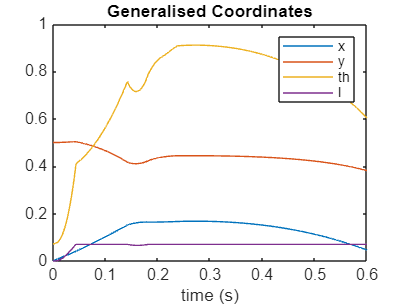

clf;
% display state of all variables
plot(sols.x,sols.y(1,:));
hold on
plot(sols.x,sols.y(2,:));
plot(sols.x,sols.y(3,:));
plot(sols.x,sols.y(4,:));
legend('x','y','th','l');
title("Generalised Coordinates");
xlabel('time (s)');
hold off

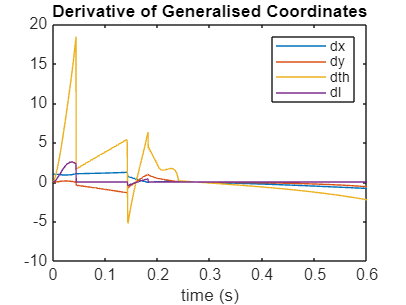


% display derivative state of all variables
plot(sols.x,sols.y(5,:));
hold on
plot(sols.x,sols.y(6,:));
plot(sols.x,sols.y(7,:));
plot(sols.x,sols.y(8,:));
legend('dx','dy','dth','dl');
title("Derivative of Generalised Coordinates");
xlabel('time (s)');
hold off

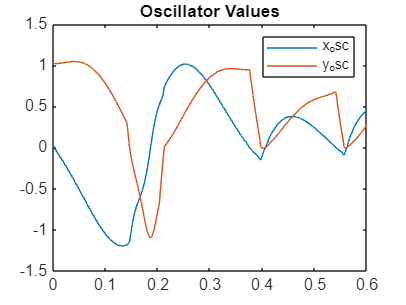


% display oscillator
plot(sols.x,sols.y(9,:));
hold on
plot(sols.x,sols.y(10,:));
legend('x_osc','y_osc');
title('Oscillator Values')
hold off

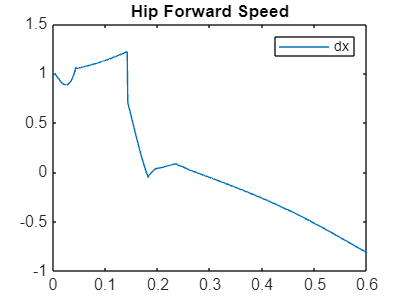


% display dx
plot(sols.x,sols.y(5,:));
legend('dx');
title('Hip Forward Speed')


% display y and dy
% plot(sols.x,sols.y(6,:));
% hold on
% plot(sols.x,sols.y(2,:));
% hold off

## Load into Simulink (and calculate force values)

if simulink
    foot = zeros(4,length(sols.x));
    grf_total = zeros(2,length(sols.x));
    t_total = zeros(1,length(sols.x));
    f_total = zeros(1,length(sols.x));
    phi_d_total = zeros(1,length(sols.x));
    dphi_d_total = zeros(1,length(sols.x));
    th_d_total = zeros(1,length(sols.x));
    dth_d_total = zeros(1,length(sols.x));
    y_osc_total = zeros(1,length(sols.x));
    u = zeros(2,length(sols.x));

    phi_sol = zeros(1,length(sols.x));
    r_sol = zeros(1,length(sols.x));
    dphi_sol = zeros(1,length(sols.x));
    dr_sol = zeros(1,length(sols.x));

    tst = osc_param(1)*ones(1,length(sols.x));
    tsw = osc_param(2)*ones(1,length(sols.x));
    kx = osc_param(3)*ones(1,length(sols.x));
    
    for i = 1:length(sols.x)
        x = sols.y(1,i); y = sols.y(2,i); th = sols.y(3,i); l = sols.y(4,i);
        dx = sols.y(5,i); dy = sols.y(6,i); dth = sols.y(7,i); dl = sols.y(8,i);
        x_osc = sols.y(9,i); y_osc = sols.y(10,i);
    
        thk_sols = thk_calc(th,l);
        dthk_sols = dthk_calc(th,l,dth,dl);
        tha_sols = tha_calc(th,l);
        dtha_sols = dtha_calc(th,l,dth,dl);
        
        foot_dynamics = foot_Func(x,y,th,l,thk_sols,tha_sols,dx,dy,dth,dl,dthk_sols,dtha_sols);
    
        foot(:,i) = foot_dynamics;
    
        grf = grf_calc(foot_dynamics);
        grf_t = grf(1); grf_n = grf(2);
        grf_total(:,i) = grf;
    
        phi_sol(i) = phi_calc(th,l);
        r_sol(i) = r_calc(th,l);
        dphi_sol(i) = dphi_calc(th,l,dth,dl);
        dr_sol(i) = dr_calc(th,l,dth,dl);

        slip = [r_sol(i),phi_sol(i),dr_sol(i),dphi_sol(i)];
    
        % update oscilating values
        [dx_osc,dy_osc] = CPG_Oscillator(x_osc,y_osc,foot_dynamics(2),foot_dynamics(4),tst(i),tsw(i));

        q = [x,y,th,l,dx,dy,dth,dl];
    
        [phi_d,dphi_d,kp,kd,ue,ur,dt_start,state,dx_filtered] = CPG_states_Hopf(sols.x(i),q,slip,foot_dynamics,y_osc,x_osc,dx_osc,kx(i),uprev,front);
    
        % ue = 0; ur = 0;
        u(:,i) = [ue;ur];
    
        th_d = max(th_calc(phi_d,l),0);
        if (th_d==0)
            dth_d = max(dth_calc(phi_d,l,dphi_d,dl),0);
        else
            dth_d = dth_calc(phi_d,l,dphi_d,dl);
        end
        
        t_total(i) = speedTorque(- kp*(th - th_d) - kd*(dth - dth_d),dth);
        % f_total(i) = F_calc((sols.x(i)-dt_start),ue,ur,l,dl);
        f_total(i) = F_calc_dF(sols.y(11,i),sols.y(12,i),ue,ur,dl);
    
        phi_d_total(i) = phi_d;
        dphi_d_total(i) = dphi_d;
        th_d_total(i) = th_d;
        dth_d_total(i) = dth_d;
        y_osc_total(i) = y_osc;
    end
    
    th_osc = atan(sols.y(10,:)./sols.y(9,:));

    time = sols.x;
    sols_out = [sols.y(1,:);sols.y(2,:);sols.y(3,:);sols.y(4,:);sols.y(5,:);sols.y(6,:);sols.y(7,:);sols.y(8,:)];
    coords_sols.time = transpose(time);
    coords_sols.signals.values = transpose(sols_out);
    
    osc_params = [tst;tsw];
    oscillator_val = [sols.y(9,:);sols.y(10,:);th_osc;osc_params];
    oscillator_sols.time = transpose(time);
    oscillator_sols.signals.values = transpose(oscillator_val);
    
    system_val = [grf_total;t_total;f_total;foot;u];
    system_sols.time = transpose(time);
    system_sols.signals.values = transpose(system_val);
    
    template_val = [r_sol;phi_sol;dr_sol;dphi_sol];
    template_sols.time = transpose(time);
    template_sols.signals.values = transpose(template_val);
    
    setpoint_val = [th_d_total;dth_d_total;phi_d_total;dphi_d_total];
    setpoint_sols.time = transpose(time);
    setpoint_sols.signals.values = transpose(setpoint_val);

    ddy_mat.time = transpose(time);
    ddy_mat.signals.values = transpose(gradient(sols.y(6,:),sols.x));

    Simulink.sdi.setRunNamingRule('MATLAB_' + string(sols.y(5,1)) + 'ms');

sim("data_inspector_full_CPG.slx");
end

## Animate (drawnow)

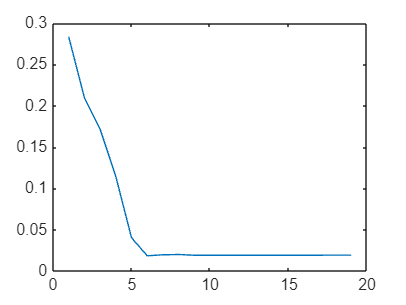

if animate
fps = 30; % Desired frame rate
dt = 1 / fps; % Time interval between frames
t_interp = sols.x(1):dt:sols.x(end); % New time vector

% Interpolate all states in sols.y
solsy_interp = interp1(sols.x, sols.y', t_interp, 'linear')';

% x_sim = sols.y(1,:);
% y_sim = sols.y(2,:);
% th_sim = sols.y(3,:);
% l_sim = sols.y(4,:);
x_sim = solsy_interp(1,:);
y_sim = solsy_interp(2,:);
th_sim = solsy_interp(3,:);
l_sim = solsy_interp(4,:);
thk_sim = thk_calc(th_sim,l_sim);
tha_sim = tha_calc(th_sim,l_sim);

x_knee = x_sim + lf*cos(th_sim);
y_knee = y_sim - lf*sin(th_sim);
x_foot = x_knee - lt*cos(thk_sim);
y_foot = y_knee - lt*sin(thk_sim);

x_piston_top = x_sim - lf_o*sin(th_sim);
y_piston_top = y_sim - lf_o*cos(th_sim);
x_piston_end = x_piston_top + lp*cos(tha_sim);
y_piston_end = y_piston_top - lp*sin(tha_sim);
x_rod_end = x_piston_end + (l_sim).*cos(tha_sim);
y_rod_end = y_piston_end - (l_sim).*sin(tha_sim);

plot(y_foot)

Elapsed time is 2.164153 seconds.


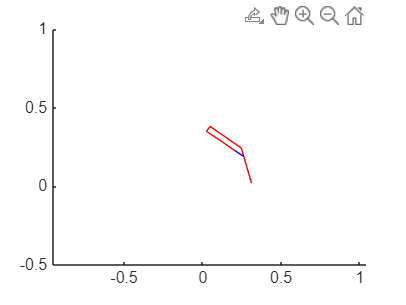

fig = figure;

ax = axes('Parent',fig);

b = animatedline(ax,'Color','b','LineWidth',1);
f = animatedline(ax,'Color','r','LineWidth',0.5);
t = animatedline(ax,'Color','r','LineWidth',0.5);
p_o = animatedline(ax,'Color','r','LineWidth',0.5);
p = animatedline(ax,'Color','r','LineWidth',0.5);
r = animatedline(ax,'Color','b','LineWidth',0.5);

axes(ax);

axis equal;
axis(ax,[(x_sim(1)-1) (x_sim(1)+1) -0.5 1]);

hold on;
tic
drawnow

for i = 1:width(solsy_interp)

    clearpoints(b);
    clearpoints(f);
    clearpoints(t);
    clearpoints(p_o);
    clearpoints(p);
    clearpoints(r);

    % axis equal;
    % axis([-1 11 -0.5 1]);
    % body
    addpoints(b,x_sim(i),y_sim(i));
    % femur
    addpoints(f,[x_sim(i), x_knee(i)],[y_sim(i), y_knee(i)]);
    % tibia
    addpoints(t,[x_knee(i), x_foot(i)],[y_knee(i), y_foot(i)]);
    % piston offset
    addpoints(p_o,[x_sim(i), x_piston_top(i)],[y_sim(i), y_piston_top(i)]);
    % piston
    addpoints(p,[x_piston_top(i), x_piston_end(i)],[y_piston_top(i), y_piston_end(i)]);
    % rod
    addpoints(r,[x_piston_end(i), x_rod_end(i)],[y_piston_end(i), y_rod_end(i)]);

    axis(ax,[(x_sim(i)-1) (x_sim(i)+1) -0.5 1]);

    drawnow
    pause(dt);

end
drawnow
toc
hold off;
end